close_system('all', 0);
close all;
addpath("Matlab Blocks\");
addpath("Matlab code\");
addpath(genpath("cpp"));

modelfile = "Simulink Models\dvbs2link.slx";
modelname = "dvbs2link";
temp_build_dir = fullfile(pwd, 'TEMP');
if ~exist(temp_build_dir, 'dir')
    mkdir(temp_build_dir);
end
Simulink.fileGenControl('set', 'CacheFolder', temp_build_dir);

CMakeBuild(); %сборка .dll

🔧 Configuring CMake...
🔨 Building library...
✅ Library built: C:\Common\Code\MATLAB\DVB-S2 Link\cpp\build\dvbs2.dll


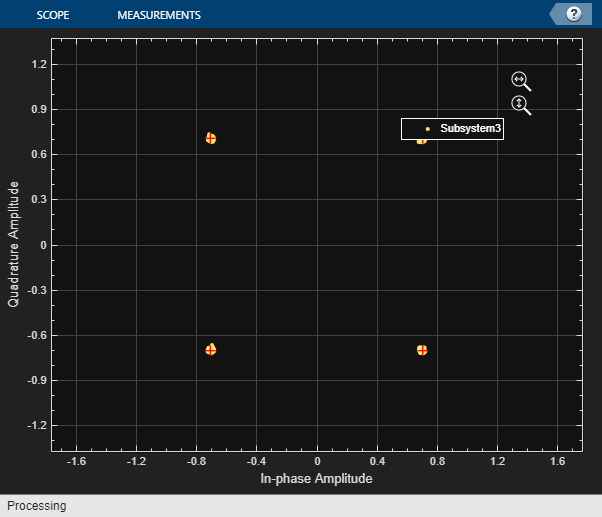


Ts = 1/10e6;
N = 24100000;
SNR = 20;

bitsIn = logical(randi([0 1], N, 1));
load("MAT files\LDPC_2_5.mat");
load("MAT files\SOF.mat");
LDPC25Matrix = sparse(PT_2_5_S(:,1), PT_2_5_S(:,2), true, 9720, 16200);
open_system(modelfile)